Import functions

(not needed for now)

addpath('./utils/');

Read image

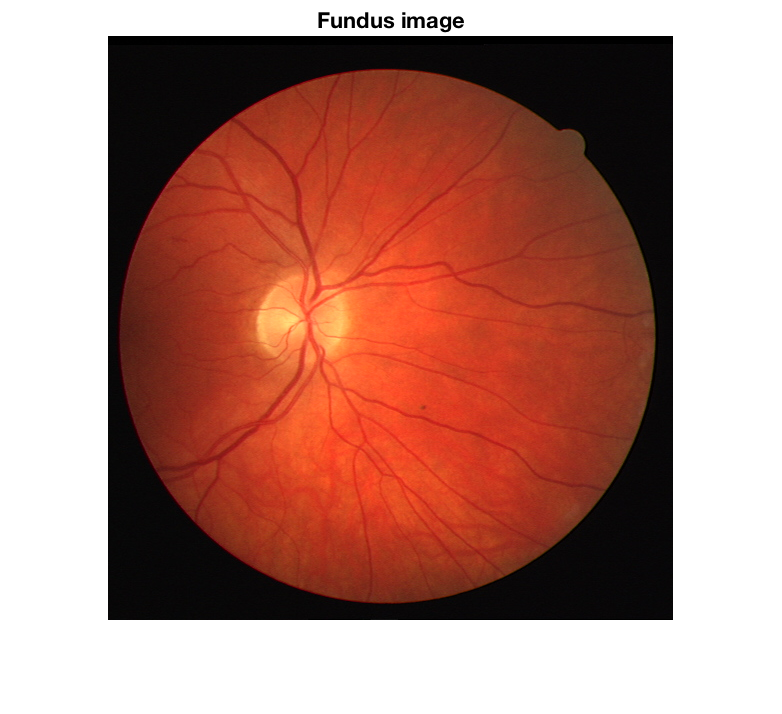

im = imread('../dataset/DRIVE/test/images/15_test.tif');
imshow(im)
title('Fundus image')

Extract green channel

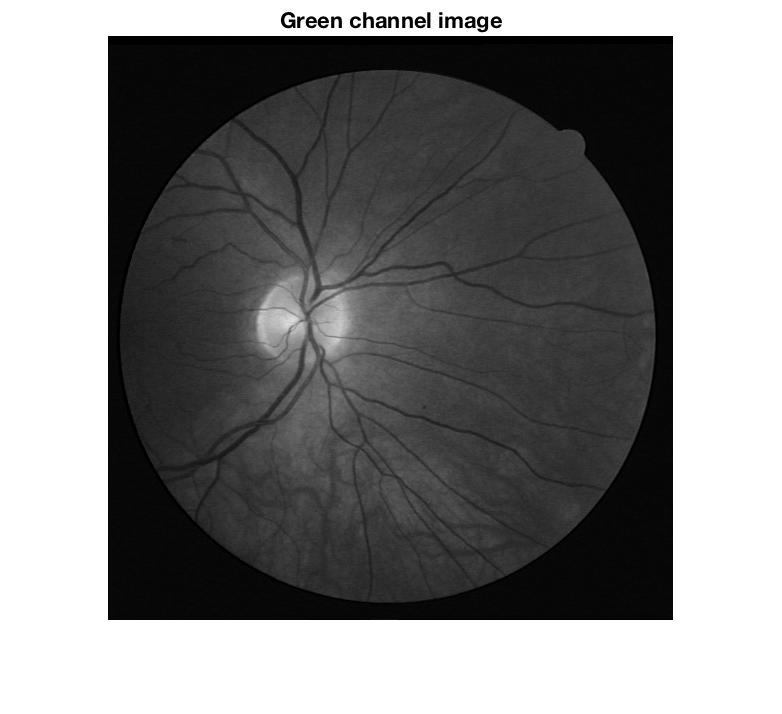

green = im(:,:,2);
imshow(green)
title('Green channel image')

Contrast-Limited Adaptive Histogram Equalization filter

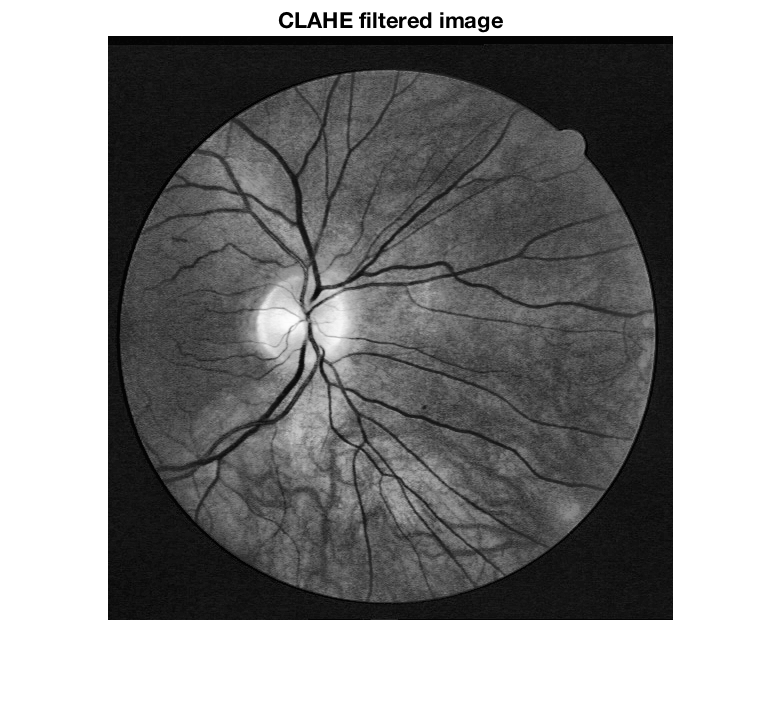

clahe = adapthisteq(green);
imshow(clahe)
title('CLAHE filtered image')

Noise reducing with median filter

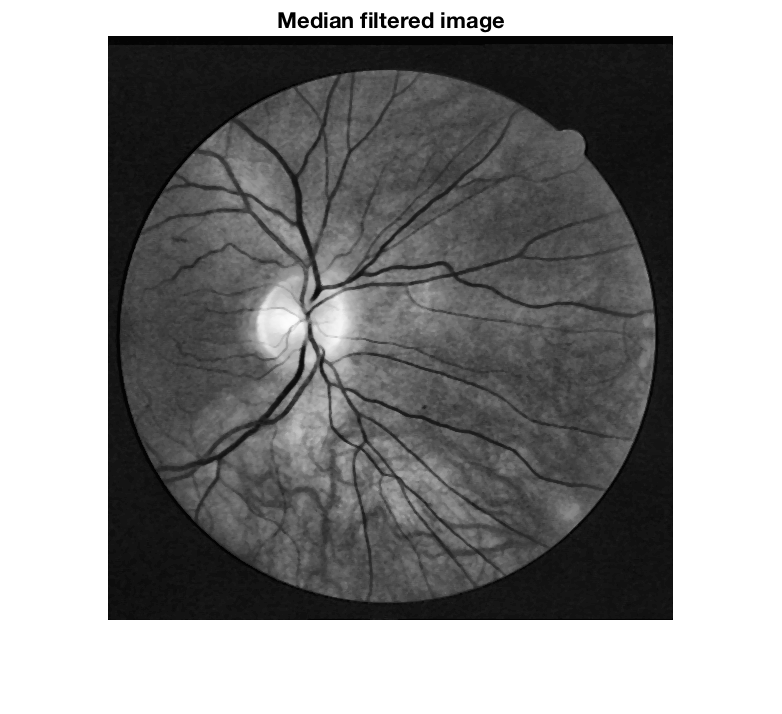

median = medfilt2(clahe);
imshow(median)
title('Median filtered image')

Use mean-C thresholding to segment blood vessels from the image

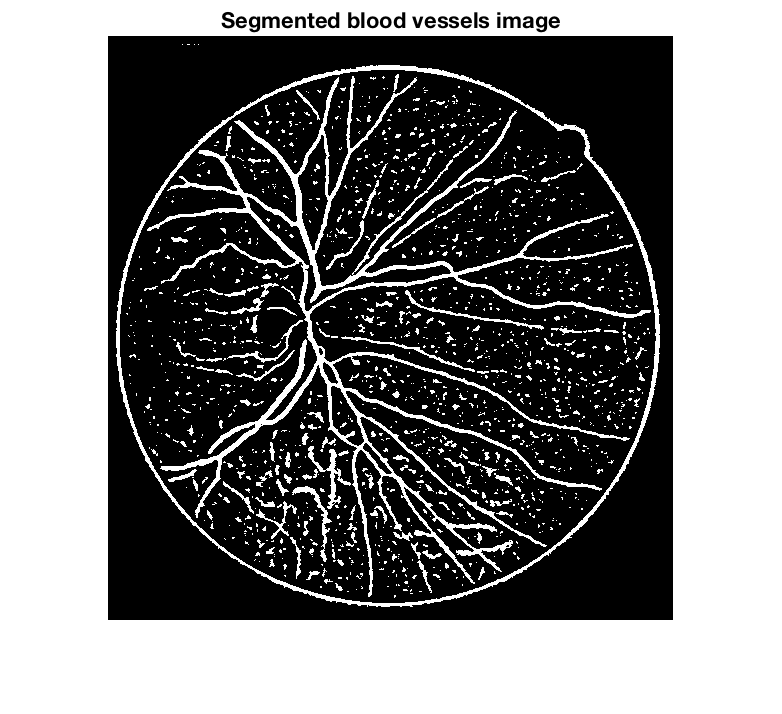

mean_c = mean_c_thresholding(median,13,0.035);
imshow(mean_c)
title('Segmented blood vessels image')

Morphological

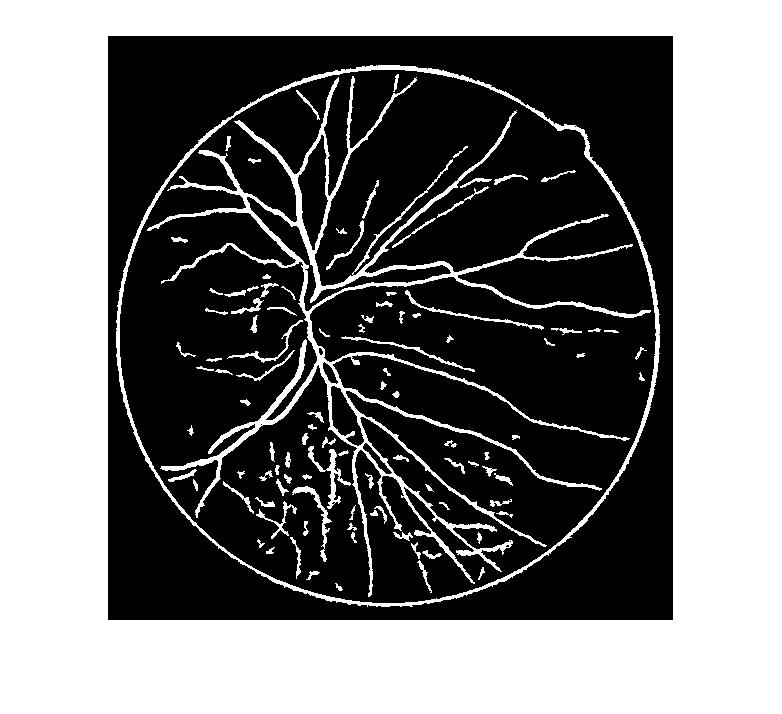

% neighbor_count_kernel = ones([3 3]);
% neighbor_count = convolve_double(mean_c,neighbor_count_kernel);
% % Init matrix
% vessels = false(size(mean_c));
% 
% for i = 1:numel(vessels)
%     if (neighbor_count(i) >= 4)
%         vessels(i) = true;
%     end
% end
% 
% vessels = bwmorph(vessels,'clean');
% vessels = bwmorph(vessels,'fill');
% imshow(vessels)

test = bwmorph(mean_c,'clean');
% test = bwmorph(test,'fill');
% test = medfilt2(test);
test = bwareafilt(test,[28 Inf]);
imshow(test)

TODO create binary mask image

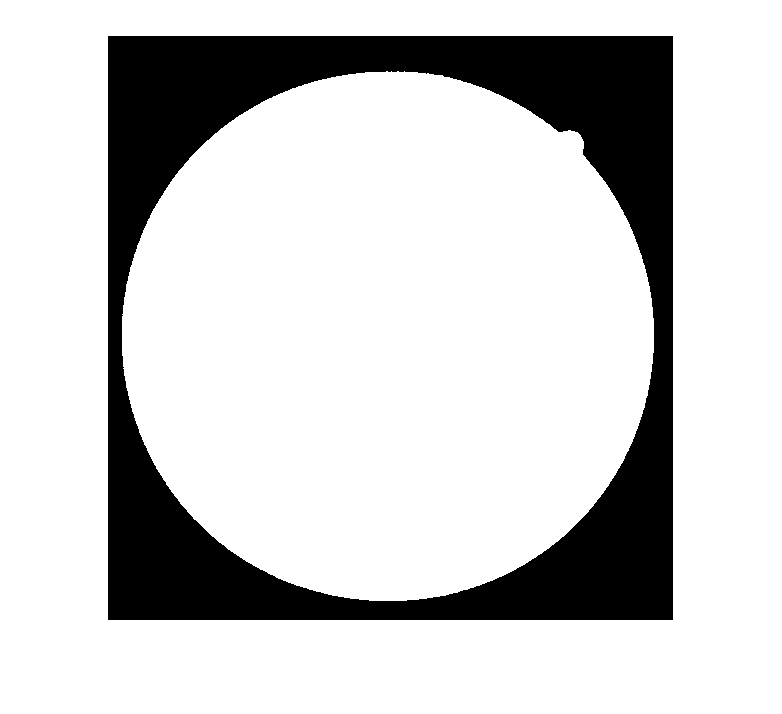

mask_thres = 10; % TODO explain this

mask = false(size(green));
for i = 1:numel(green)
    if (green(i) > mask_thres)
        mask(i) = true;
    end
end

% 1 pixel disk shape image opening
mask = imopen(mask,strel('disk',1));

% Suppress rough white edge pixel twice
for i = 1:2
    mask = imerode(mask,[0,1,0;1,1,1;0,1,0]);
end

imshow(mask)

Final segmented image

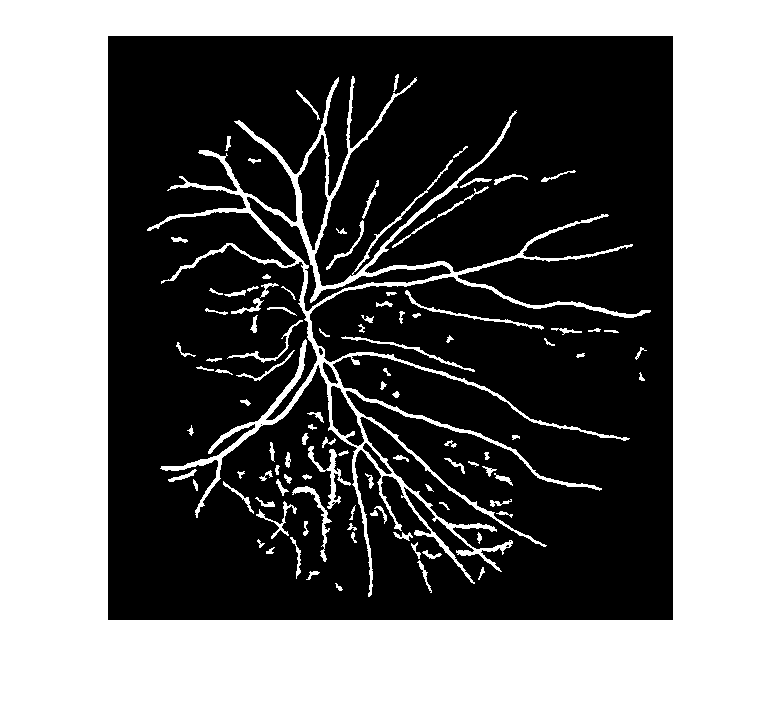

res = bitand(test,mask);
imshow(res)